%% 光学设计仿真实验——自由曲面透镜轮廓计算
clc; clear; close all;

%% 参数设置
N = 1000;               % 光通量能量单元份数
d = 100;                % 透镜高度（任意单位）
n = 1.49;               % 材料折射率

%% 预分配数组
T = zeros(1,N+1);       % 光线出射角（与竖直方向夹角）
r = zeros(1,N+1);       % 出射点距光轴的径向高度
x = zeros(1,N+1);       % 自由曲面轮廓点横坐标
y = zeros(1,N+1);       % 自由曲面轮廓点纵坐标

%% 初始值
T(1) = 0;
r(1) = 0;
x(1) = 0;
y(1) = 7;             % 起始高度（可微调）

R = d * tan(pi/3);      % 最大出射高度对应半径

%% 1. 计算出射角序列 T(i)
for i = 2:N+1
    T(i) = acos( cos(2*T(i-1)) - 2/N ) / 2;
end

%% 2. 计算出射高度序列 r(j)
for j = 2:N+1
    r(j) = R * ((j-1)/N)^0.5;
end

%% 3. 迭代计算自由曲面轮廓 (x,y)
Nx = 0;                 % 入射光线方向 x 分量（初始垂直向下）
Ny = 1;                 % 入射光线方向 y 分量

for k = 2:N+1
    % 计算当前轮廓点坐标
    x(k) = ( (Nx/Ny)*x(k-1) + y(k-1) ) / ( tan(pi/2 - T(k)) + Nx/Ny );
    y(k) = tan(pi/2 - T(k)) * x(k);

    % 出射光线单位矢量 (ox, oy)
    ang_out = atan( (d - y(k)) / (r(k) - x(k)) );
    ox = cos(ang_out);
    oy = sin(ang_out);

    % 入射光线单位矢量 (ix, iy)
    ix = sin(T(k));
    iy = cos(T(k));

    % 矢量折射公式（Snell 定律）
    den = sqrt( 1 + n^2 - 2*n*(ox*ix + oy*iy) );
    Nx = (ox - n*ix) / den;
    Ny = (oy - n*iy) / den;
end



%% 5. 绘图
figure;
plot(x, y, 'LineWidth', 1.2);

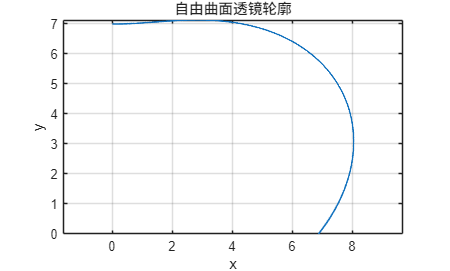

xlabel('x');
ylabel('y');
title('自由曲面透镜轮廓');
grid on;
axis equal;